% Script para Discretização das Funções de Transferência (Item 5)
% Comparando ZOH, Tustin e Forward Euler - VERSÃO CORRIGIDA

clear all; close all; clc;

%% 1. Definição de Parâmetros
% Frequência de amostragem do sistema digital
Fs = 10000; % Hz
T = 1/Fs;   % Período de amostragem (s)

% Parâmetros do Conversor Buck
L = 1.752e-3;   % Indutância (H)
C = 14.48e-6;   % Capacitância (F)
R = 10;         % Resistência de carga (Ω)

% Parâmetros do Filtro Sallen-Key
R1_filt = 13e3;     R2_filt = 5.6e3;
C1_filt = 0.1e-6;   C2_filt = 0.0033e-6;

%% 2. Criação dos Modelos Contínuos em s
s = tf('s');

% Função de Transferência Contínua do Conversor Buck
G_buck_c = (1/(L*C)) / (s^2 + (1/(R*C))*s + 1/(L*C));

% Função de Transferência Contínua do Filtro Sallen-Key
G_filtro_c = (1/(R1_filt*C1_filt*R2_filt*C2_filt)) / ...
             (s^2 + s*(1/(R2_filt*C1_filt) + 1/(R1_filt*C1_filt)) + ...
              1/(R1_filt*C1_filt*R2_filt*C2_filt));

disp('--- Modelos Contínuos G(s) ---');

--- Modelos Contínuos G(s) ---


fprintf('\nFunção de Transferência do Conversor Buck G_buck(s):\n');


Função de Transferência do Conversor Buck G_buck(s):


G_buck_c


G_buck_c =
 
         3.942e07
  -----------------------
  s^2 + 6906 s + 3.942e07
 
Continuous-time transfer function.
Model Properties


fprintf('\nFunção de Transferência do Filtro Sallen-Key G_filtro(s):\n');


Função de Transferência do Filtro Sallen-Key G_filtro(s):


G_filtro_c


G_filtro_c =
 
         4.163e07
  -----------------------
  s^2 + 2555 s + 4.163e07
 
Continuous-time transfer function.
Model Properties



%% 3. Discretização

% --- A. Métodos Padrão (ZOH e Tustin) usando c2d ---
G_buck_zoh = c2d(G_buck_c, T, 'zoh');
G_buck_tustin = c2d(G_buck_c, T, 'tustin');
G_filtro_zoh = c2d(G_filtro_c, T, 'zoh');
G_filtro_tustin = c2d(G_filtro_c, T, 'tustin');

% =========================================================================
% --- B. Método Forward Euler (Implementação por Substituição) - CORRIGIDO ---
% =========================================================================
% Define-se a variável z e a aproximação s = (z-1)/T
z = tf('z', T);
s_euler = (z-1)/T;

% --- Para o Conversor Buck ---
% Obtemos os coeficientes dos polinômios do numerador e denominador
[num_c_buck, den_c_buck] = tfdata(G_buck_c, 'v');
% Reconstruímos a função de transferência manualmente com a variável s_euler
% Isso evita o erro de "invalid subscript"
num_z_buck = num_c_buck(1)*s_euler^2 + num_c_buck(2)*s_euler + num_c_buck(3);
den_z_buck = den_c_buck(1)*s_euler^2 + den_c_buck(2)*s_euler + den_c_buck(3);
G_buck_euler = num_z_buck / den_z_buck;
G_buck_euler = minreal(G_buck_euler); % Simplifica a expressão

% --- Para o Filtro Sallen-Key ---
[num_c_filtro, den_c_filtro] = tfdata(G_filtro_c, 'v');
% Reconstruímos a função de transferência
num_z_filtro = num_c_filtro(1)*s_euler^2 + num_c_filtro(2)*s_euler + num_c_filtro(3);
den_z_filtro = den_c_filtro(1)*s_euler^2 + den_c_filtro(2)*s_euler + den_c_filtro(3);
G_filtro_euler = num_z_filtro / den_z_filtro;
G_filtro_euler = minreal(G_filtro_euler);
% =========================================================================

%% 4. Exibição dos Resultados no Console
disp('--- Modelos Discretos G(z) ---');

--- Modelos Discretos G(z) ---


fprintf('\n[BUCK] G_buck(z) - Método ZOH:\n');


[BUCK] G_buck(z) - Método ZOH:


G_buck_zoh


G_buck_zoh =
 
    0.1537 z + 0.1218
  ----------------------
  z^2 - 1.226 z + 0.5013
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


fprintf('\n[BUCK] G_buck(z) - Método Tustin:\n');


[BUCK] G_buck(z) - Método Tustin:


G_buck_tustin


G_buck_tustin =
 
  0.06825 z^2 + 0.1365 z + 0.06825
  --------------------------------
       z^2 - 1.249 z + 0.5217
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


fprintf('\n[BUCK] G_buck(z) - Método Forward Euler:\n');


[BUCK] G_buck(z) - Método Forward Euler:


G_buck_euler


G_buck_euler =
 
          0.3942
  ----------------------
  z^2 - 1.309 z + 0.7036
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties



fprintf('\n-----------------------------------\n');


-----------------------------------



fprintf('\n[FILTRO] G_filtro(z) - Método ZOH:\n');


[FILTRO] G_filtro(z) - Método ZOH:


G_filtro_zoh


G_filtro_zoh =
 
    0.185 z + 0.1697
  ---------------------
  z^2 - 1.42 z + 0.7745
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


fprintf('\n[FILTRO] G_filtro(z) - Método Tustin:\n');


[FILTRO] G_filtro(z) - Método Tustin:


G_filtro_tustin


G_filtro_tustin =
 
  0.08448 z^2 + 0.169 z + 0.08448
  -------------------------------
      z^2 - 1.455 z + 0.7926
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


fprintf('\n[FILTRO] G_filtro(z) - Método Forward Euler:\n');


[FILTRO] G_filtro(z) - Método Forward Euler:


G_filtro_euler


G_filtro_euler =
 
         0.4163
  ---------------------
  z^2 - 1.745 z + 1.161
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


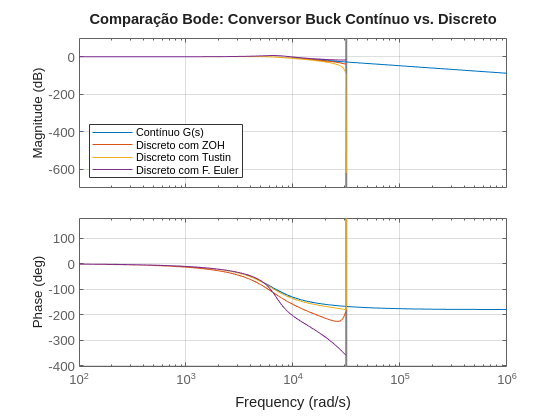



%% 5. Análise Gráfica e Comparação
% Comparação dos Diagramas de Bode para o Conversor Buck
figure(1);
bode(G_buck_c, G_buck_zoh, G_buck_tustin, G_buck_euler);
title('Comparação Bode: Conversor Buck Contínuo vs. Discreto');
legend('Contínuo G(s)', 'Discreto com ZOH', 'Discreto com Tustin', 'Discreto com F. Euler', 'Location', 'southwest');
grid on;


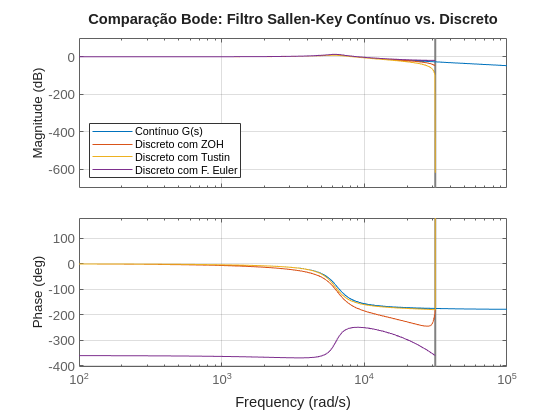

% Comparação dos Diagramas de Bode para o Filtro Sallen-Key
figure(2);
bode(G_filtro_c, G_filtro_zoh, G_filtro_tustin, G_filtro_euler);
title('Comparação Bode: Filtro Sallen-Key Contínuo vs. Discreto');
legend('Contínuo G(s)', 'Discreto com ZOH', 'Discreto com Tustin', 'Discreto com F. Euler', 'Location', 'southwest');
grid on;
